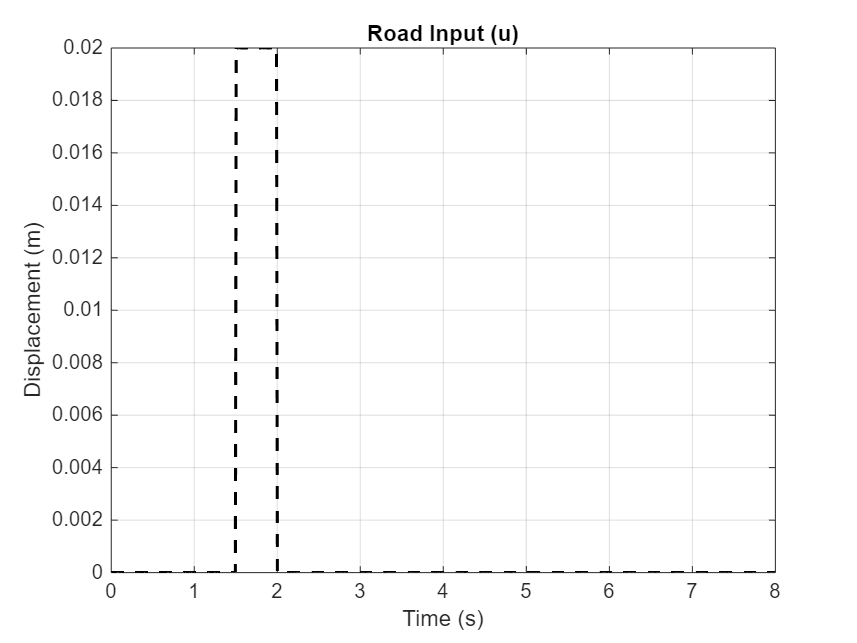

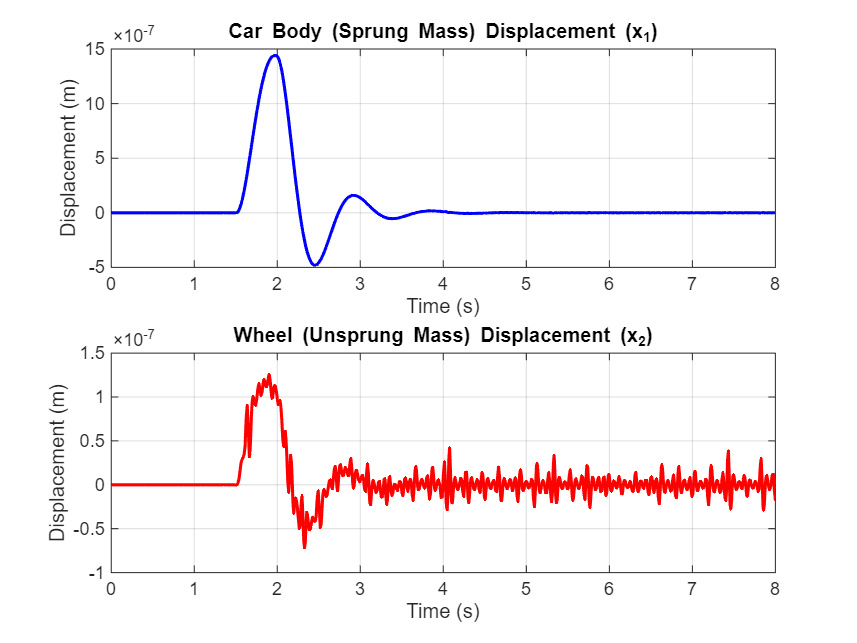

% State-space matrices and dynamics (Function)
function dxdt = quarter_car_dynamics(t, x, A, B, road_input, road_input_time)
    % Interpolate road input at the current time
    u = interp1(road_input_time, road_input, t, 'linear', 'extrap');
    
    % Compute state derivatives using state-space representation
    dxdt = A * x + B * u;
end

% Function to plot results
function plot_results(time, x1_array, x2_array, road_input, road_input_time)

    % Plot road input
    figure;
    road_input_interpolated = interp1(road_input_time, road_input, time, 'linear', 'extrap'); % Interpolate road input
    plot(time, road_input_interpolated, 'k--', 'LineWidth', 1.5);
    title('Road Input (u)');
    xlabel('Time (s)');
    ylabel('Displacement (m)');
    grid on;

    % Car Body displacements
    figure;
    subplot(2,1,1);
    plot(time, x1_array, 'b', 'LineWidth', 1.5);
    title('Car Body (Sprung Mass) Displacement (x_1)');
    xlabel('Time (s)');
    ylabel('Displacement (m)');
    grid on;

    % Wheel displacements
    subplot(2,1,2);
    plot(time, x2_array, 'r', 'LineWidth', 1.5);
    title('Wheel (Unsprung Mass) Displacement (x_2)');
    xlabel('Time (s)');
    ylabel('Displacement (m)');
    grid on;

end

% Sedan ------------------------------------------------------------------------------------------------------

% Car Body / Chassis (Sprung Mass)
m1 = 375; % 1/4 of Car body's Weight (kg)
x1 = 0; % Initial Disp of car body (m)
x2 = 0; % Initial Velocity car body = x1_dot (m/s)
% Spring & Damper in-between masses
kc = 20000; % Suspension spring stiffness (N/m)
cs = 2000; % Damping coefficient (Damper) of suspension (Ns/m) "C Shock"
% Wheel + Tire + Upright (Unsprung Mass)
m2 = 40; % Mass of Wheel + Tire + Upright = unsprung mass (kg)
x3 = 0; % Initial Disp of wheel (m)
x4 = 0; % Initial velocity of wheel = x3_dot (m/s)
kt = 250000; % Tire stiffness (N/m) (CONTACT WITH ROAD)

% Simulation Variables
dt = 0.001; % Time step (s)
T = 8; % 8-second simulation time (s)
road_input_time = 0:dt:T-dt; % Time array
N = T / dt; % # of simulation steps (8000 steps in this case)

% Road profile Step Input (Road variation such as elevation, roughness, etc.)
road_input = zeros(1, N); % 1-Row Vector with N # of zeros (Flat road)
road_input(1500:2000) = 0.02; % 0.02m bump from 1.5-2 second frame (=500 steps)

% State-space matrices
% Define state-space system for the quarter car model
% State vector: [x1, x2, x3, x4] (displacements and velocities)
A = [0, 1, 0, 0; 
     -kc/m1, -cs/m1, kc/m1, cs/m1; 
     0, 0, 0, 1; 
     kc/m2, cs/m2, -(kc+kt)/m2, -cs/m2]; % Dynamics matrix
B = [0; 1/m1; 0; 0]; % Force impulse for m1
% B = [0; 0; 0; kt/m2]; % Force impulse for m2
C = eye(4); % 4x4 identity matrix, ensures state variables are outputted as it states
D = zeros(4, 1); % No direct feedthrough

% Initial conditions
x0 = [x1; x2; x3; x4]; % Initial state vector

% Call ode45 to simulate the quarter car system and store in [time, X]
% time: vector containing time points (0-8 in this case)
% X: Vector x = [x1 x2 x3 x4] 
[time, X] = ode45(@(t, x) quarter_car_dynamics(t, x, A, B, road_input, road_input_time), [0 T], x0);

% Extract results (Display displacement of car body and wheel)
x1_array = X(:, 1); % Displacement of sprung mass
x2_array = X(:, 3); % Displacement of unsprung mass

% Call plotting function to plot simulation results
plot_results(time, x1_array, x2_array, road_input, road_input_time);

% -------------------------------------------------------------------

% Natural Frequency (Hz)
k_eff = kc; % Effective stiffness (spring stiffness in suspension)
m_eff = m1; % Effective mass (sprung mass)
c_eff = cs; % Damping coefficient of suspension

% Natural frequency in Hz
fn = (1 / (2 * pi)) * sqrt(k_eff / m_eff);
disp(['Natural Frequency (f_n): ', num2str(fn), ' Hz']);

Natural Frequency (f_n): 1.1623 Hz


% Damping ratio
zeta = c_eff / (2 * sqrt(m_eff * k_eff));
disp(['Damping Ratio (ζ): ', num2str(zeta)]);

Damping Ratio (ζ): 0.36515


% Damping Classification
if zeta > 1
    damping_classification = 'Overdamped';
elseif zeta == 1
    damping_classification = 'Critically Damped';
else
    damping_classification = 'Underdamped';
end
disp(['Damping Classification: ', damping_classification]);

Damping Classification: Underdamped


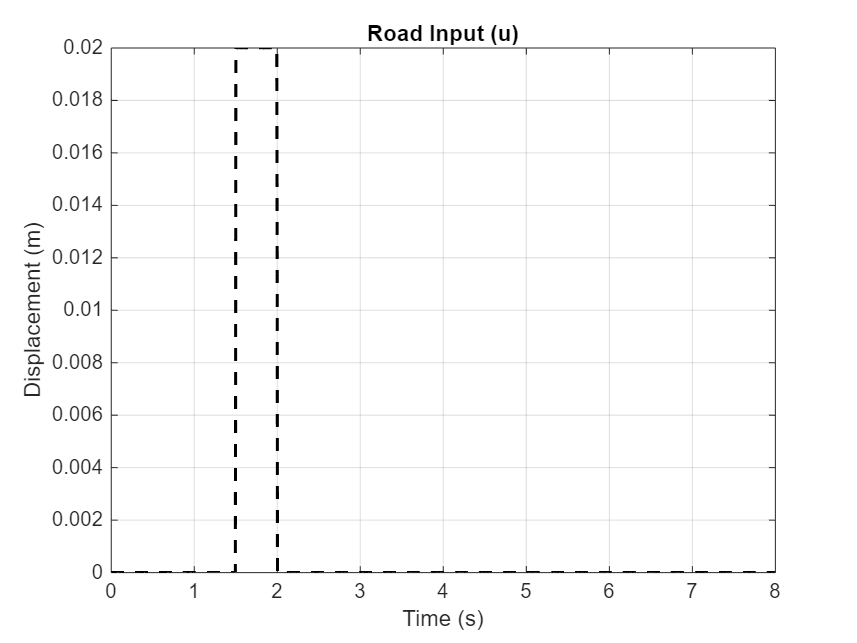

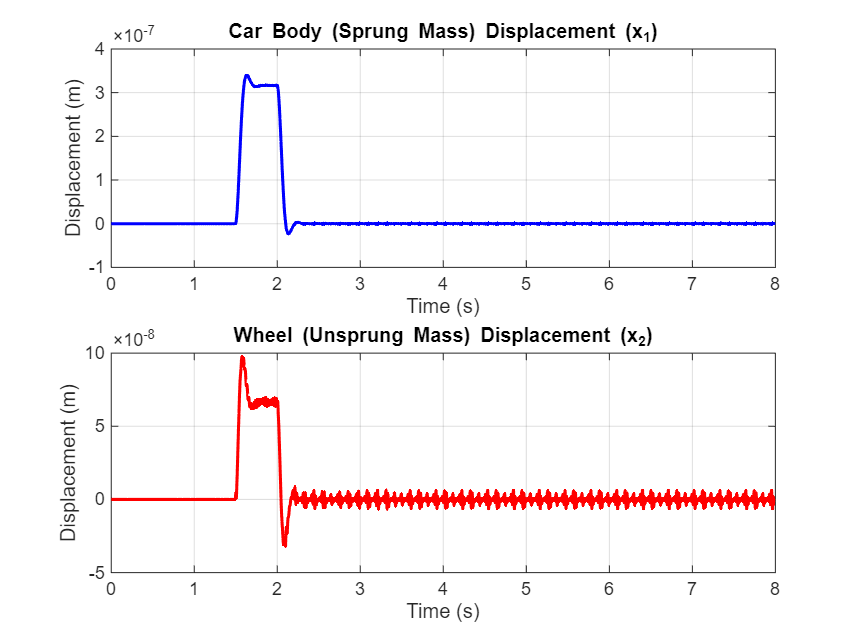


% Formula Race Car (Lighter, stiffer suspension) ---------------------------------------------------------------------------

% Car Body / Chassis (Sprung Mass)
m1 = 120; % 1/4 of Car body's Weight (kg)
x1 = 0; % Initial Disp of car body (m)
x2 = 0; % Initial Velocity car body = x1_dot (m/s)
% Spring & Damper in-between masses
kc = 80000; % Suspension spring stiffness (N/m)
cs = 5000; % Damping coefficient (Damper) of suspension (Ns/m) "C Shock"
% Wheel + Tire + Upright (Unsprung Mass)
m2 = 25; % Mass of Wheel + Tire + Upright = unsprung mass (kg)
x3 = 0; % Initial Disp of wheel (m)
x4 = 0; % Initial velocity of wheel = x3_dot (m/s)
kt = 300000; % Tire stiffness (N/m) (CONTACT WITH ROAD)

% Simulation Variables
dt = 0.001; % Time step (s)
T = 8; % 8-second simulation time (s)
road_input_time = 0:dt:T-dt; % Time array
N = T / dt; % # of simulation steps (8000 steps in this case)

% --- (CODE BELOW) ORIGINAL QUARTER CAR MODEL USING ROAD PROFILE & FORCE IMPULSE ON 1 MASS:
% Road profile Step Input (Road variation such as elevation, roughness, etc.)
road_input = zeros(1, N); % 1-Row Vector with N # of zeros (Flat road)
road_input(1500:2000) = 0.02; % 0.02m bump from 1.5-2 second frame (=500 steps)

% State-space matrices
% Define state-space system for the quarter car model
% State vector: [x1, x2, x3, x4] (displacements and velocities)
A = [0, 1, 0, 0; 
     -kc/m1, -cs/m1, kc/m1, cs/m1; 
     0, 0, 0, 1; 
     kc/m2, cs/m2, -(kc+kt)/m2, -cs/m2]; % Dynamics matrix
B = [0; 1/m1; 0; 0]; % Force impulse for m1
% B = [0; 0; 0; kt/m2]; % Force impulse for m2
C = eye(4); % 4x4 identity matrix, ensures state variables are outputted as it states
D = zeros(4, 2); % No direct feedthrough

% Initial conditions
x0 = [x1; x2; x3; x4]; % Initial state vector

% Call ode45 to simulate the quarter car system and store in [time, X]
% time: vector containing time points (0-8 in this case)
% X: Vector x = [x1 x2 x3 x4] 
[time, X] = ode45(@(t, x) quarter_car_dynamics(t, x, A, B, road_input, road_input_time), [0 T], x0);

% Extract results (Display displacement of car body and wheel)
x1_array = X(:, 1); % Displacement of sprung mass
x2_array = X(:, 3); % Displacement of unsprung mass

% Call plotting function to plot simulation results
plot_results(time, x1_array, x2_array, road_input, road_input_time);

% -------------------------------------------------------------------

% Natural Frequency (Hz)
k_eff = kc; % Effective stiffness (spring stiffness in suspension)
m_eff = m1; % Effective mass (sprung mass)
c_eff = cs; % Damping coefficient of suspension

% Natural frequency in Hz
fn = (1 / (2 * pi)) * sqrt(k_eff / m_eff);
disp(['Natural Frequency (f_n): ', num2str(fn), ' Hz']);

Natural Frequency (f_n): 4.1094 Hz


% Damping ratio
zeta = c_eff / (2 * sqrt(m_eff * k_eff));
disp(['Damping Ratio (ζ): ', num2str(zeta)]);

Damping Ratio (ζ): 0.80687


% Damping Classification
if zeta > 1
    damping_classification = 'Overdamped';
elseif zeta == 1
    damping_classification = 'Critically Damped';
else
    damping_classification = 'Underdamped';
end
disp(['Damping Classification: ', damping_classification]);

Damping Classification: Underdamped


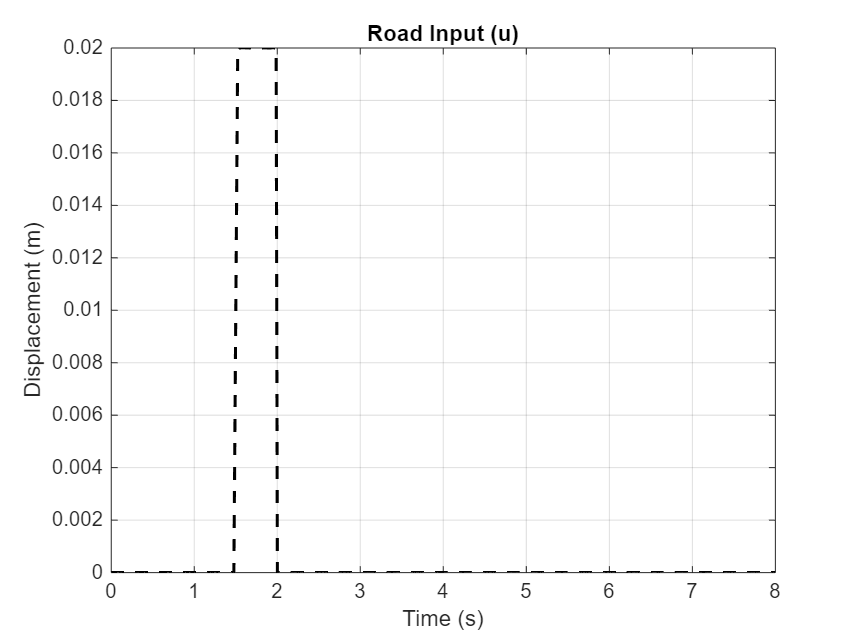

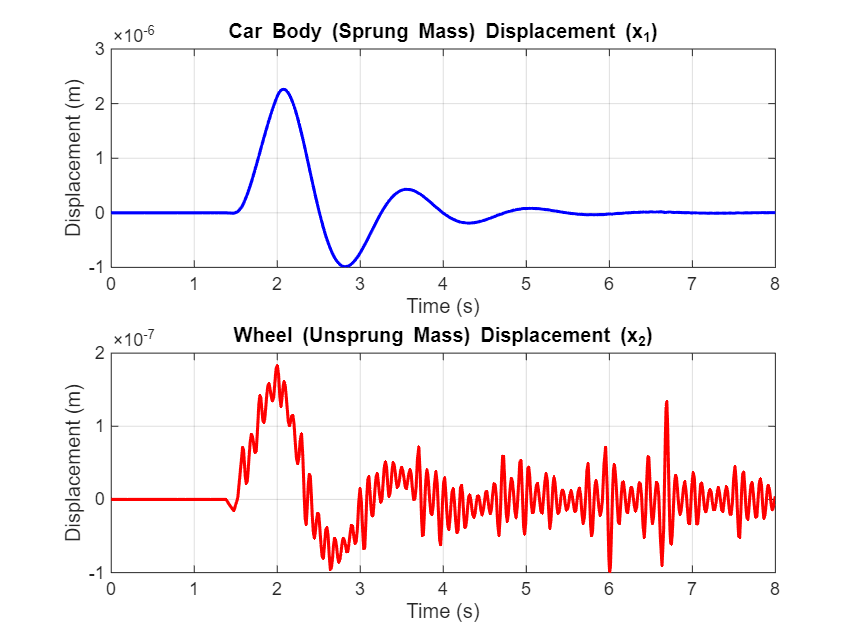


% Truck (Heavier, softer suspension)---------------------------------------------------------------------------------------

% Car Body / Chassis (Sprung Mass)
m1 = 600; % 1/4 of Car body's Weight (kg)
x1 = 0; % Initial Disp of car body (m)
x2 = 0; % Initial Velocity car body = x1_dot (m/s)
% Spring & Damper in-between masses
kc = 12000; % Suspension spring stiffness (N/m)
cs = 1500; % Damping coefficient (Damper) of suspension (Ns/m) "C Shock"
% Wheel + Tire + Upright (Unsprung Mass)
m2 = 60; % Mass of Wheel + Tire + Upright = unsprung mass (kg)
x3 = 0; % Initial Disp of wheel (m)
x4 = 0; % Initial velocity of wheel = x3_dot (m/s)
kt = 180000; % Tire stiffness (N/m) (CONTACT WITH ROAD)

% Simulation Variables
dt = 0.001; % Time step (s)
T = 8; % 8-second simulation time (s)
road_input_time = 0:dt:T-dt; % Time array
N = T / dt; % # of simulation steps (8000 steps in this case)

% --- (CODE BELOW) ORIGINAL QUARTER CAR MODEL USING ROAD PROFILE & FORCE IMPULSE ON 1 MASS:
% Road profile Step Input (Road variation such as elevation, roughness, etc.)
road_input = zeros(1, N); % 1-Row Vector with N # of zeros (Flat road)
road_input(1500:2000) = 0.02; % 0.02m bump from 1.5-2 second frame (=500 steps)

% State-space matrices
% Define state-space system for the quarter car model
% State vector: [x1, x2, x3, x4] (displacements and velocities)
A = [0, 1, 0, 0; 
     -kc/m1, -cs/m1, kc/m1, cs/m1; 
     0, 0, 0, 1; 
     kc/m2, cs/m2, -(kc+kt)/m2, -cs/m2]; % Dynamics matrix
B = [0; 1/m1; 0; 0]; % Force impulse for m1
% B = [0; 0; 0; kt/m2]; % Force impulse for m2
C = eye(4); % 4x4 identity matrix, ensures state variables are outputted as it states
D = zeros(4, 2); % No direct feedthrough

% Initial conditions
x0 = [x1; x2; x3; x4]; % Initial state vector

% Call ode45 to simulate the quarter car system and store in [time, X]
% time: vector containing time points (0-8 in this case)
% X: Vector x = [x1 x2 x3 x4] 
[time, X] = ode45(@(t, x) quarter_car_dynamics(t, x, A, B, road_input, road_input_time), [0 T], x0);

% Extract results (Display displacement of car body and wheel)
x1_array = X(:, 1); % Displacement of sprung mass
x2_array = X(:, 3); % Displacement of unsprung mass

% Call plotting function to plot simulation results
plot_results(time, x1_array, x2_array, road_input, road_input_time);

% -------------------------------------------------------------------

% Natural Frequency (Hz)
k_eff = kc; % Effective stiffness (spring stiffness in suspension)
m_eff = m1; % Effective mass (sprung mass)
c_eff = cs; % Damping coefficient of suspension

% Natural frequency in Hz
fn = (1 / (2 * pi)) * sqrt(k_eff / m_eff);
disp(['Natural Frequency (f_n): ', num2str(fn), ' Hz']);

Natural Frequency (f_n): 0.71176 Hz


% Damping ratio
zeta = c_eff / (2 * sqrt(m_eff * k_eff));
disp(['Damping Ratio (ζ): ', num2str(zeta)]);

Damping Ratio (ζ): 0.27951


% Damping Classification
if zeta > 1
    damping_classification = 'Overdamped';
elseif zeta == 1
    damping_classification = 'Critically Damped';
else
    damping_classification = 'Underdamped';
end
disp(['Damping Classification: ', damping_classification]);

Damping Classification: Underdamped



% Sedan (With altered displacement) ------------------------------------------------------------------------------------

% Car Body / Chassis (Sprung Mass)
m1 = 375; % 1/4 of Car body's Weight (kg)
x1 = 0; % Initial Disp of car body (m)
x2 = 0; % Initial Velocity car body = x1_dot (m/s)
% Spring & Damper in-between masses
kc = 20000; % Suspension spring stiffness (N/m)
cs = 2000; % Damping coefficient (Damper) of suspension (Ns/m) "C Shock"
% Wheel + Tire + Upright (Unsprung Mass)
m2 = 40; % Mass of Wheel + Tire + Upright = unsprung mass (kg)
x3 = 0; % Initial Disp of wheel (m)
x4 = 0; % Initial velocity of wheel = x3_dot (m/s)
kt = 250000; % Tire stiffness (N/m) (CONTACT WITH ROAD)

% Simulation Variables
dt = 0.001; % Time step (s)
T = 8; % 8-second simulation time (s)
road_input_time = 0:dt:T-dt; % Time array
N = T / dt; % # of simulation steps (8000 steps in this case)

% --- (CODE BELOW) ORIGINAL QUARTER CAR MODEL USING ROAD PROFILE & FORCE IMPULSE ON 1 MASS:
% Road profile Step Input (Road variation such as elevation, roughness, etc.)
road_input = zeros(1, N); % 1-Row Vector with N # of zeros (Flat road)
road_input(1500:2000) = 0.02; % 0.02m bump from 1.5-2 second frame (=500 steps)

% State-space matrices
% Define state-space system for the quarter car model
% State vector: [x1, x2, x3, x4] (displacements and velocities)
A = [0, 1, 0, 0; 
     -kc/m1, -cs/m1, kc/m1, cs/m1; 
     0, 0, 0, 1; 
     kc/m2, cs/m2, -(kc+kt)/m2, -cs/m2]; % Dynamics matrix
B = [0; 1/m1; 0; 0]; % Force impulse for m1
% B = [0; 0; 0; kt/m2]; % Force impulse for m2
C = eye(4); % 4x4 identity matrix, ensures state variables are outputted as it states
D = zeros(4, 2); % No direct feedthrough

% Initial conditions
x0 = [x1; x2; x3; x4]; % Initial state vector

% Call ode45 to simulate the quarter car system and store in [time, X]
% time: vector containing time points (0-8 in this case)
% X: Vector x = [x1 x2 x3 x4] 
[time, X] = ode45(@(t, x) quarter_car_dynamics(t, x, A, B, road_input, road_input_time), [0 T], x0);

% Extract results (Display displacement of car body and wheel)
x1_array = X(:, 1); % Displacement of sprung mass
x2_array = X(:, 3); % Displacement of unsprung mass

% Call plotting function to plot simulation results
plot_results(time, x1_array, x2_array, road_input, road_input_time);

% -------------------------------------------------------------------

% Natural Frequency (Hz)
k_eff = kc; % Effective stiffness (spring stiffness in suspension)
m_eff = m1; % Effective mass (sprung mass)
c_eff = cs; % Damping coefficient of suspension

% Natural frequency in Hz
fn = (1 / (2 * pi)) * sqrt(k_eff / m_eff);
disp(['Natural Frequency (f_n): ', num2str(fn), ' Hz']);

Natural Frequency (f_n): 1.1623 Hz


% Damping ratio
zeta = c_eff / (2 * sqrt(m_eff * k_eff));
disp(['Damping Ratio (ζ): ', num2str(zeta)]);

Damping Ratio (ζ): 0.36515


% Damping Classification
if zeta > 1
    damping_classification = 'Overdamped';
elseif zeta == 1
    damping_classification = 'Critically Damped';
else
    damping_classification = 'Underdamped';
end
disp(['Damping Classification: ', damping_classification]);

Damping Classification: Underdamped



% TO DO -------------------------------------------------------------------

% (DONE) Look at natural frequency (root m over k) in Hz
% (DONE) Damping ratio, similar to frequency, looking at mass and spring,
% (DONE) over/under damped
% (DONE) Compare race car and passenger car, change parameters, and
% (DONE) Interpret outputs
